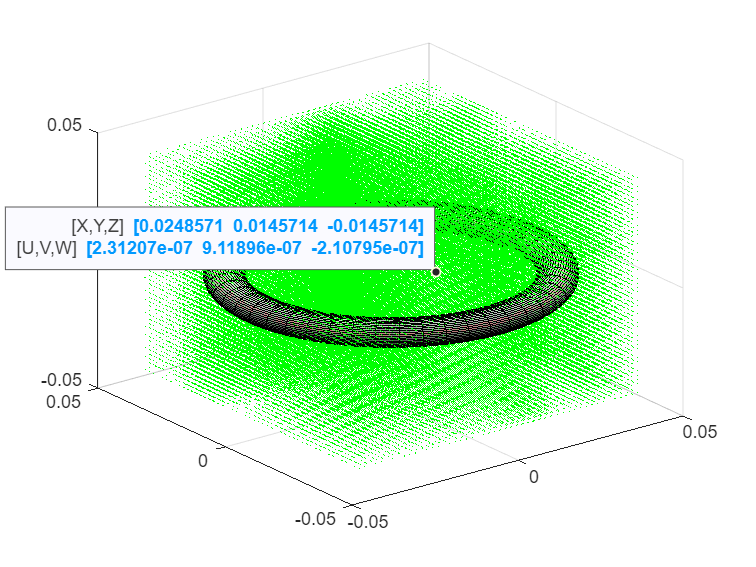

%Building Magnetic Field Animator

%This program intends to construct the magnetic field of a current-carrying
%wire. For some, a simple calculation will just do the trick, and making
%that is simple enough. This program extends the scope to creating a full
%magnetic field of the wire as a visual element. In the future, hopefully
%we can animate the magnetic field about the loop.

%Inputs: Current, Radius, Observation Points

%Current: The current flowing through the wire
Current = 4; %Measured in Amps

%Radius: The Radius of the Wire Loop. If there is no radius, it is simply a
%straight wire.
Radius = 0.04;

%Thickness: The thickness of the wire
Thickness = 0.005;

%Choice1: Here is where the the choice is made between animating the
%magnetic field and doing a simple calculation for "calibration."

%If 1: You are going for a simple calculation with a specific Observation
%Point Pre-determined. Code will probably be altered to a degree to ensure
%that the above constants will be consistent for calibration purposes.

%If 2: You have chosen to go down the route of animating the magnetic
%field. Here you will have more customability in what you are looking for;
%you can change the Current flowing through the wire and the radius of the
%loop.

Choice1 = input("If you are wanting a simple calculation, enter 1. If you are wanting a calculation, enter 2. ");
switch Choice1 
    case 1
        
        Observation_Point = [0.04, 0.02, 0.01];
        [MagneticField,GradientField] = MagneticFieldCalc(Current,Observation_Point,Radius);
        disp(MagneticField)
        
    case 2
        %Calculations Section:

        %Setting up Observation Points
        [X_Range, Y_Range, Z_Range] = meshgrid(linspace(-1.05*Radius,1.05*Radius,10));
        X_Flat = X_Range(:);
        Y_Flat = Y_Range(:);
        Z_Flat = Z_Range(:);

        Observation_Points = cat(2,X_Flat, Y_Flat, Z_Flat);
        
        %Perfoming the Calculations:
        MagneticField = zeros(size(Observation_Points));
        for i = 1:1000
            [MagneticField,GradientField] = MagneticFieldCalc(Current,Observation_Points(i,:),Radius);
        end

        %Plotting the Shapes
        figure

        %Plotting the Wire
        %Angles done in a mesh grid 
        [U, V] = meshgrid(linspace(0,2*pi,50));
        %Note the element-wise multiplication. Normal multiplication causes
        %issues that made the Torus-shape (the wire) to be far wider than
        %needed. (U = 0, V = 0) ended up with WireX = 2.248... instead of
        %Wire X = .045
        WireX = (Radius+Thickness*cos(V)).*cos(U);
        WireY = (Radius+Thickness*cos(V)).*sin(U);
        WireZ = Thickness*sin(V);
        Wire = surf(WireX,WireY,WireZ);
        colormap(gray)
        %Making Shape transluscent to see the Wire below visible)
        Wire.FaceAlpha = 0.75;
        hold on

        %Plotting the Current: Quiver Plot)
        %Current is going to be in a 2D Plot, so no need to calculate Z
        %component.
        CurrentX = Radius*cos(linspace(0,2*pi,50));
        CurrentY = Radius*sin(linspace(0,2*pi,50));
        %Quiver command needs gradients of the components
        Current_dX = gradient(CurrentX);
        Current_dY = gradient(CurrentY);
        %Quiver plot will show the "direction" of the current for
        %visualization.
        quiver3(CurrentX,CurrentY,zeros(size(CurrentX)), Current_dX,Current_dY,zeros(size(CurrentX)),'r');
        hold on
        
        [Bx,By,Bz] = meshgrid(GradientField(:,1),GradientField(:,2),GradientField(:,3));
        Bx = reshape(Bx,size(X_Range));
        By = reshape(By,size(X_Range));
        Bz = reshape(Bz,size(X_Range));


        quiver3(X_Range,Y_Range,Z_Range,Bx,By,Bz,'g')

end